# Julio 2021

#### Cuestiones

#### Cuestión 1

**Una imgen monocroma (16 niveles de gris) de tamaño 10Kpixeles tiene el siguiente histograma**

**h(16) = [0 0 0 0 500 100 2000 400 6000 0 0 1000 0 0 0 0]**

**a) Calcular y representar el histograma ecualizado**

**b) Calcular la codificación Huffman de la imagen**

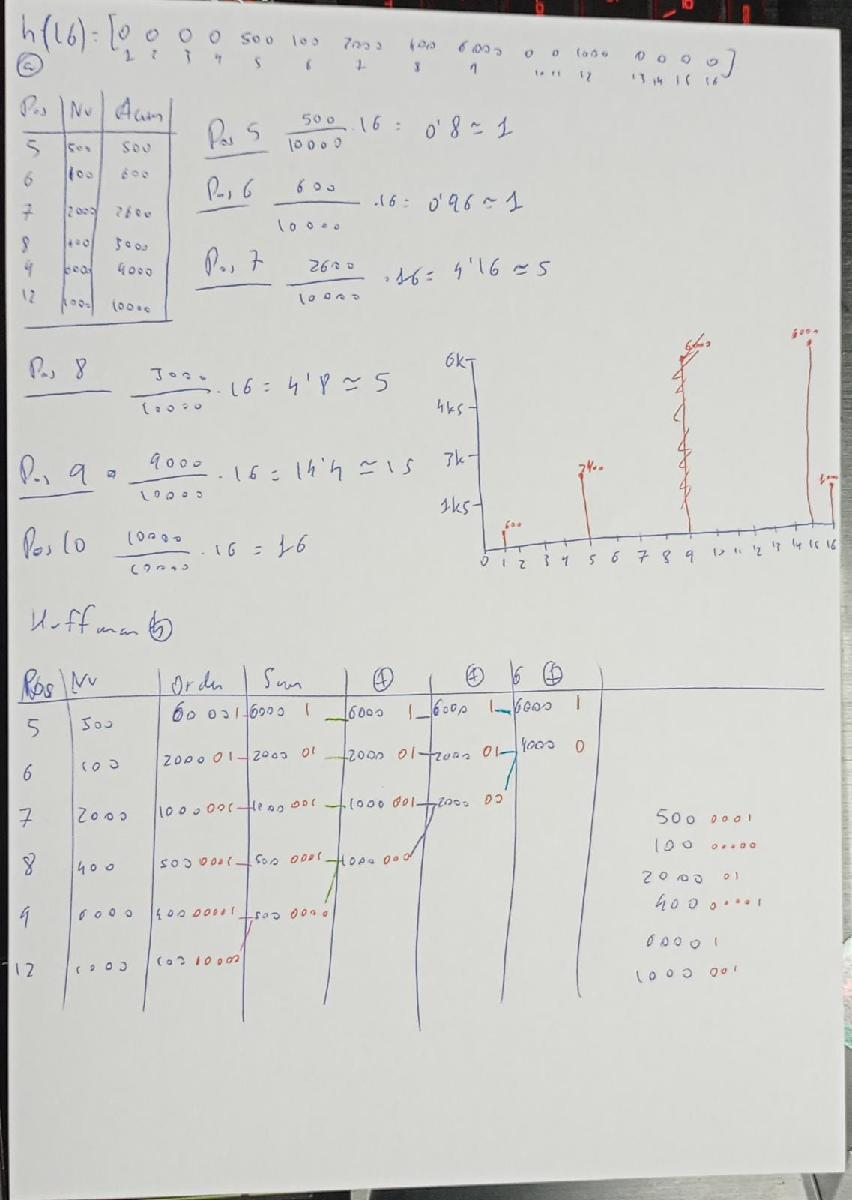

#### **Cuestión 2**

**Enumera mediante una tabla las diferencias que existen entre las ténicas de Red neuronal Artificial y Deep Learning**

Las redes neuronales artificiales convencionales emulan el funcionamiento de nuestro cerebro a partir de ortorgar pesos sinápticos a los distintos datos, almacenan el conocimiento  distribuido. Se basan en una serie de 'neuronas' artificiales unidad que permiten generar un proceso, el machine learning requiere conocimiento experto, tiempo y ajustes manueales. El usuario es quien tiene que programar el algoritmo extractor de características y tiene un porcentaje de error más alto

En cuanto al Deep Learning, se encuentra inspirado en el funcionamiento de nuestro cerebro, pero dista de ser igual a este, tiene múltiples capas de proceso, puede aprender tanto de manera supervisada como no supervisada y su jerarquía se basa en capas *bottom-up*, lo que indica que cada pequeña parte se realiza con detalle para poder generar sistemas cada vez más grandes. La propia red extrae las características que necesita para clasificar y su nivel de error es más bajo que en las redes neuronales.

#### **Cuestión 3**

**¿Para qué puede servir calcular la diferencia entre una imagen binarizada y la misma imagen erosionada? Razona la respuesta**

Calcular la diferencia entre una imagen binarizada y la misma imagen pero erosionada sirve para poder obtener los bordes de las figuras de una imagen. La erosión te elimina los bordes previamente nombrados, mientras que el binarizar hace que los distintos colores en escala de grises de una imagen se separen en blancos (valores mayores o iguales a 168) y negros (valores menores a 168). De esta manera al hacer la diferencia obtendremos únicamente los bordes de la imagen original

#### **Cuestión 4**

**En el modelo de color HSI ¿Que parte deberíamos tratar si queremos hacer una ecualización de histograma?**

El modelo de color HSI devuelve una matriz con 3 capas, H, S e I. Si queremos trabajar con la saturación tomaremos la S, y si queremos trabajar con el brillo tomaremos la I, y la H es la capa Hue, que nos permite trabajar con el tono (longitud de onda dominante en una mezcla de longitudes de onda luminosas)

#### **Problemas**

#### **Problema 1**

**Tenemos una imagen (256x256 px) degradada, si suponemos conocida la función de transferencia de dicha degradación.**

**1) ¿Cuál sería el primer algoritmo que probariamos para restaurar dicha imagen? ¿Qué posibles probleams puede presentar, y como se podrían solucionar?**

FIltro inverso, ya que es más sencillo de implementar que el filtro Wiener.el problema que presenta este filtro es que si en la imagen hay ruido, el filtro lo amplificará, entorpeciendo la restauración

**2) Si la función de transferencia es: **


$$H\left(u,v\right)\;=\;e^{-\frac{u^2 +v^2 }{2\cdot \sigma^2 }}$$


**Programe un algoritmo en MATLAB que aplique el alhoritmo descrito anteriormente**

Llamamos a la imagen

Im = imread(Im);
Im = double(Im);

Obtenemos el tamaño de la imagen

[N, M] = size(Im);

Inicializamos la salida H

H = zeros(N,M);

Preparamos el bucle en el cuál calcularemos la función de transferencia

for u = 1:N
    for v = 1:M

        H(u,v) = exp(-(u^2 + v^2)/(2*(sigma^2)));

    end
end
H = H.^-1;
H = H./max(max(H));

Para obtener la imagen recuperada

Im_Recuperada = Im.*H;
imshow(Im_Recuperada)

**3) Modifica el algoritmo anterior para implementar una posible solución si observamos que el algoritmo no se ha comportado como esperábamos**

Llamamos a la imagen

Im = imread(Im);
Im = double(Im);

Obtenemos el tamaño de la imagen

[N, M] = size(Im);

Inicializamos la salida H

H = zeros(N,M);

Preparamos el bucle en el cuál calcularemos la función de transferencia

Calculamos la K. El valor K será igual a la fft del ruido al cuadrado, divido entre la fft de la imagen al cuadrado

K = 0.5

for u = 1:N
    for v = 1:M
        
        H(u,v) = exp(-(u^2 + v^2)/(2*(sigma^2)));

    end
end
H_2 = H.^2;
Im_Resultante = (1./H)*(H_2./(H_2)+K).* Im;

Para obtener la imagen recuperada

imshow(Im_Resultante)

#### Problema 2

**Se desea programar un compresor con pérdidas mediante un predictor de 1er orden. El cuantificador debe tener el número de niveles de cuantificación Q=16**

**a) Programar el predictor de formar estructurada mediante funciones**

Im = imread('');
Im = double(Im);

Obtenemos el tamaño

[N, M] = size(Im);

Calculamos el valor máximo de Gris de la Imagen

Gris_Max = nextpow2(max(max(Im)));

Tenemos el valor de Q

Q = 16;x

Inicializamos todos los valores

e = zeros(N,M); %Error
fp =zeros(N,M); %Foto predecida
ec = zeros(N,M); %Error cuantificado
fc = zeros(N,M); %Imagen cuantificada

Debemos de inicializar el primer pixel de la imagen

fc(1,1) = Im(1,1);

Obtenemos el valor de K, el tamaño del escalón, a más grande el tamaño del escalón peor resultado obtendremos

K = Gris_Max/Q;

Con un bucle calcularemos primero el valor de la primera columna. Empezaremos desde el segundo bit porque el primero ya está inicializado

for i=2:N

fp es igual a la fc anterior

e es igual a Im - fp

ec es igual a K*round(e/K)

fc es igual a fp+ec

fp(i,1) = fc(i-1, 1);
e(i,1) = Im(i,1)- fp(i,1);
ec(i,1) = K*round(e(i,1)/K);
fc(i,1) = fp(i,1)+ec(i,1);
end

Ahora con un doble bucle calcularemos el resto de valores de la matriz

for i = 1:N
    for j = 2:M

para fp ponemos i,j-1 para obtener el valor justo de la columna anterior

        fp(i,j) = fc(i, j-1);
        e(i,j) = Im(i,j) - fp(i,j);
        ec(i,j) = K*round(e(i,j)/K);
        fc(i,j) = fp(i,j) + ec(i,j)
    end
end

**b) ¿Como podríamos mejorar la calidad del compresor sin aumentar la Q? Razone la respuesta**

Haciendolo de segundo orden porque de esta manera la imagen predecida será mejor

#### **Problema 3**

**La imagen de la figura adjunta contiene rectas de 3 colores: rojo, azul y verde.**

**Se desea detectar la línea más larga de la imagen cuyo color sea AZUL. La imagen se encuentra en el archivo "colores.jpg", cuyos colores no son totalmente puros. Para programar la función se dispone de la función siguiente:**

**H = Hough(imbin, Nm, Nb)**

**dónde imbin es la imagen binarizada (contiene 1 y zeros), Nm y Nb son el número de valores m y b respectivamente y H es la tabla de acumulación que devuelve la función como resultado**

**Programar una función que imprima la pendiente ma y la ordenada en el origen ba de la recta AZUL de mayor longitud a partir de la imagen de entrada colores.jpg**